# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

### Connectivity Methods:

### **Mutual Information**

Mutual information is a simple but robust framework for quantifying the amount of information that is shared between two variables   

Mutual information is a flexible analysis framework that can be custom-tailored to identify patterns of connectivity regardless of the distributions of the data (e.g., linear, nonlinear, circular)  

### **Entropy**  

Here, the term entropy is used to refer to Shannon entropy from information theory. It is the amount of information, or “ surprise, ”  

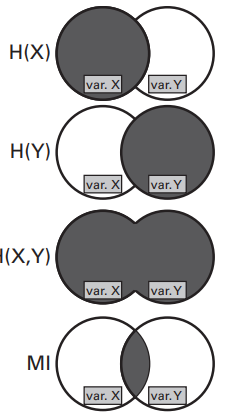

mutual information (MI)  

where *H *is the measure of entropy, *p *is the probability of observing the *ith *value of the bin series data *x*, and *n *is the number of bins.   

To compute entropy with continuous data such as an EEG, you first bin the data as you would to create a histogram. Binning continuous data can be done using the Matlab function hist. Next, compute the probability that a value of the data would fall into each bin. This is simply the bin count divided by the sum of all bin counts. Then, multiply the probability value by the logarithm-base-2 of that probability value. Finally, sum all the probability-logprobability values and multiply by –1. The log of a number less than 1 is negative, and because probabilities are always less than one, the summation will always be negative. Multiplying by –1 therefore flips the sign of the result.   

### Feature

- Entropy is also unrelated to the temporal structure of the data. That is, you could randomly shuffle around the time points, and the entropy would not change. This makes entropy a very different quantity than the Fourier transform, which could change drastically if the temporal structure of the data is altered.  

- You can see that entropy is related only to probabilities and distributions, not to the original scale of the data. This means that entropy and mutual information are not subject to power-law scaling effects over frequency and thus do not require baseline normalizations  

- It is possible that there are zero probability values for some bins. This is problematic because the logarithm of zero is undefined (-Inf in Matlab). Thus, in Matlab code, you should add a very small number inside the logarithm term to prevent taking the logarithm of zero

- Entropy can be computed over time or over trials (see figure 26.4 for an illustration of analyses over time vs. over trials). However, unlike some other measures that are computed over time *or *over trials, entropy (and, therefore, mutual information) can also be computed over time *and *over trials simultaneously.  

**For feature 1:**

% create two signals
time    = 0:.0001:1;
signal1 = sin(2*pi*10*time);
signal2 = rand(size(signal1))*2-1; % uniform random numbers in the same scale as the sine wave

% plot signals
figure
subplot(221)
plot(time,signal1)
set(gca,'xlim',[time(1) time(end)])
subplot(222)
plot(time,signal2,'r')
set(gca,'xlim',[time(1) time(end)])

% bin data (via Matlab function hist)
nbins = 50;
[hdat1,x1] = hist(signal1,nbins);
[hdat2,x2] = hist(signal2,nbins);

% convert histograms to probability values
hdat1 = hdat1./sum(hdat1);
hdat2 = hdat2./sum(hdat2);

% plot histograms
subplot(223)
plot(x1,hdat1)
hold on
plot(x2,hdat2,'r')
legend({'Sine wave';'Random data'})
xlabel('Value bins')
ylabel('Probability')

subplot(224)
plot(sort(signal1))
hold on
plot(sort(signal2),'r')
set(gca,'xlim',[0 length(signal1)])

% The following code using the 'eval' command may seem a bit needlessly
% complex, but it introduces you to this useful Matlab function. The
% main advantage here is to call different variables inside a loop,
% which would otherwise not be possible because it is the variable
% names that are different, not indices into variables. For example,
% notice how the variables hdat1 and hdat2 are called.
for i=1:2
    eval([ 'entro(' num2str(i) ') = -sum(hdat' num2str(i) '.*log2(hdat' num2str(i) '+eps));' ]);
end

% the following code will do this same thing:
% entro(1) = -sum(hdat1.*log2(hdat1+eps));
% entro(2) = -sum(hdat2.*log2(hdat2+eps));

disp([ 'Entropies of sine wave and random noise are ' num2str(entro(1)) ' and ' num2str(entro(2)) '.' ]);


### **Number of Bins**

There are statistical guidelines for determining an appropriate number of bins to use in a histogram. The guideline preferred here is called the Freedman-Diaconis rule (Freedman and Diaconis 1981), which states that the optimal number of histogram bins is related to the interquartile range and to the number of data points.  

in which *Q *is the interquartile range of data distribution *X *(that is, the numerical distance between the 25th and the 75th percentiles of the data distribution), *n *is the total number of data points, and *max(x) *and *min(x) *indicate the maximum and minimum values in data *X*.  

% range of bin numbers
nbins = 10:2000;

entropyByBinSize=zeros(size(nbins));
for nbini=1:length(nbins)
    
    % bin data, transform to probability, and eliminate zeros
    hdat = hist(signal1,nbins(nbini));
    hdat = hdat./sum(hdat);
    
    % compute entropy
    entropyByBinSize(nbini) = -sum(hdat.*log2(hdat+eps));
end
% optimal number of bins for histogram based on a few different guidelines
n = length(signal1);
maxmin_range = max(signal1)-min(signal1);

% note: the function iqr (inter-quartile range) is in the stats toolbox. 
% If you don't have this toolbox, you can write your own similar function
% by sorting the values, finding the values that are 25% and 75% of the
% sorted distribution, and then subtracting the 25% number from the 75% number.
fd_bins      = ceil(maxmin_range/(2.0*iqr(signal1)*n^(-1/3))); % Freedman-Diaconis 
scott_bins   = ceil(maxmin_range/(3.5*std(signal1)*n^(-1/3))); % Scott
sturges_bins = ceil(1+log2(n)); % Sturges

figure
subplot(211)
% plot up to 50 bins
[junk,maxNbins] = min(abs(nbins-50)); % index of nbins that most closely matches 50
plot(nbins(1:maxNbins),entropyByBinSize(1:maxNbins))

hold on
plot([fd_bins fd_bins],get(gca,'ylim'),'m','linew',2)
plot([scott_bins scott_bins],get(gca,'ylim'),'k','linew',2)
plot([sturges_bins sturges_bins],get(gca,'ylim'),'r','linew',2)

legend({'entropy';'Freedman-Diaconis';'Scott';'Sturges'})
xlabel('Number of bins'), ylabel('Entropy')

subplot(223)
[y,x]=hist(signal1,fd_bins);
h=bar(x,y,'histc');
set(h,'linestyle','none');
set(gca,'xlim',[min(signal1) max(signal1)*1.1])
xlabel('Value'), ylabel('Count')
title('Optimal number of bins (FD rule)')

subplot(224)
[y,x]=hist(signal1,2000);
h=bar(x,y,'histc');
set(gca,'xlim',[min(signal1) max(signal1)]*1.05)
xlabel('Value'), ylabel('Count')
title('Too many bins (2000)')

**Calculating Entropy**

load sampleEEGdata

% entropy over all sensors
time4entropy = [  100  400 ]; % in ms
base4entropy = [ -400 -100 ]; % in ms
topo_entropy = zeros(size(EEG.chanlocs));

timeidx=zeros(size(time4entropy)); baseidx=zeros(size(base4entropy)); 
for i=1:2
    [junk,timeidx(i)] = min(abs(EEG.times-time4entropy(i)));
    [junk,baseidx(i)] = min(abs(EEG.times-base4entropy(i)));
end

for chani=1:EEG.nbchan
    
    % entropy during task
    tempdat = EEG.data(chani,timeidx(1):timeidx(2),:);
    hdat = hist(tempdat(:),25);
    hdat = hdat./sum(hdat);
    task_entropy =  -sum(hdat.*log2(hdat+eps));
    
    % entropy during pre-stim baseline
    tempdat = EEG.data(chani,baseidx(1):baseidx(2),:);
    hdat = hist(tempdat(:),25);
    hdat = hdat./sum(hdat);
    base_entropy =  -sum(hdat.*log2(hdat+eps));
    
    % compute entropy
    topo_entropy(chani) = task_entropy - base_entropy;
end

figure
% Note: topoplot is a function in the eeglab toolbox
topoplot(topo_entropy,EEG.chanlocs,'maplimits',[-.5 .5],'plotrad',.53,'electrodes','off','numcontour',0);



% entropy over time in one electrode (fcz or po8)
sensor4entropy = 'fcz';
times2save     = -300:50:1200;
timewindow     = 400; % ms

timewindowidx = round(timewindow/(1000/EEG.srate)/2);
times2saveidx = zeros(size(times2save));
for i=1:length(times2save)
    [junk,times2saveidx(i)]=min(abs(EEG.times-times2save(i)));
end

electrodeidx = find(strcmpi(sensor4entropy,{EEG.chanlocs.labels}));

timeEntropy = zeros(1,length(times2save));

for timei = 1:length(times2save)
    
    tempdata = EEG.data(electrodeidx,times2saveidx(timei)-timewindowidx:times2saveidx(timei)+timewindowidx,1:30);
    hdat = hist(tempdata(:),25);
    hdat = hdat./sum(hdat);
    
    % compute entropy
    timeEntropy(1,timei) = -sum(hdat.*log2(hdat+eps));
    
    
    tempdata = EEG.data(electrodeidx,times2saveidx(timei)-timewindowidx:times2saveidx(timei)+timewindowidx,end-30:end);
    hdat = hist(tempdata(:),25);
    hdat = hdat./sum(hdat);
    
    % compute entropy
    timeEntropy(2,timei) = -sum(hdat.*log2(hdat+eps));
end

figure
plot(times2save,timeEntropy)
xlabel('Time (ms)'), ylabel('Entropy (bits)')
title([ 'Entropy over time from electrode ' sensor4entropy ])
legend({'First 30 trials';'last 30 trials'})

**Joint Entropy**

Joint entropy is the total entropy of a pair of variables. The formula for joint entropy follows.  

In practice, joint entropy is computed slightly differently from how entropy is computed. With entropy you need to know the distributions of individual variables, but with joint entropy you need to know the codistributions of the two variables. This can be done in Matlab by creating two nested loops, one loop over bins of variable *X *and one loop over bins of variable *Y*. Inside the double loop, count the number of times that the two variables are in the same distribution bins. After this double loop, you have a joint probability matrix, with each element in the matrix reflecting the probability that a particular set of values occurred within one bin.  

% Note about this figure: The panels use the same code but with different
% input signals. Comment out some of the lines below to recreate each panel.

% right panel: random noise
signal1 = rand(size(signal1))*2-1;
signal2 = rand(size(signal1))*2-1;

% center panel: one pure sine wave and one sine wave plus random noise
signal1 = sin(2*pi*10*time);
signal2 = signal1 + randn(size(signal1))/2;

% left panel: one pure sine wave and its inverse
signal1 = sin(2*pi*10*time);
signal2 = -signal1;


% determine the optimal number of bins for each variable
n            = length(signal1);
maxmin_range = max(signal1)-min(signal1);
fd_bins1     = ceil(maxmin_range/(2.0*iqr(signal1)*n^(-1/3))); % Freedman-Diaconis 

n            = length(signal2);
maxmin_range = max(signal2)-min(signal2);
fd_bins2     = ceil(maxmin_range/(2.0*iqr(signal2)*n^(-1/3))); % Freedman-Diaconis 

% and use the average...
fd_bins = ceil((fd_bins1+fd_bins2)/2);


% bin data (using histc this time)
edges = linspace(min(signal1),max(signal1),fd_bins+1);
[nPerBin1,bins1] = histc(signal1,edges);

edges = linspace(min(signal2),max(signal2),fd_bins+1);
[nPerBin2,bins2] = histc(signal2,edges);

% compute joint frequency table
jointprobs = zeros(fd_bins);
for i1=1:fd_bins
    for i2=1:fd_bins
        jointprobs(i1,i2) = sum(bins1==i1 & bins2==i2);
    end
end

jointprobs = jointprobs./sum(jointprobs(:));

figure
subplot(211)
plot(time,signal1)
subplot(212)
plot(time,signal2)

figure
imagesc(jointprobs)
colormap gray
set(gca,'clim',[0 .01],'ydir','normal')
colorbar
xlabel('Signal 2 bin'), ylabel('Signal 1 bin')

figure
subplot(221)
x = 0:.001:1;
y = x;
plot(x,y,'.')
title([ 'MI=' num2str(mutualinformationx(x,y)) ', r_s=' num2str(corr(x(:),y(:),'type','s')) ])
axis square

subplot(222)
x = 0:.001:1;
y = -x.^3;
plot(x,y,'.')
title([ 'MI=' num2str(mutualinformationx(x,y)) ', r_s=' num2str(corr(x(:),y(:),'type','s')) ])
axis square

subplot(223)
x=cos(0:.01:2*pi);
y=sin(0:.01:2*pi);
plot(x,y,'.')
title([ 'MI=' num2str(mutualinformationx(x,y)) ', r_s=' num2str(corr(x(:),y(:),'type','s')) ])
axis square

subplot(224)
x=[cos(0:.01:2*pi) cos(0:.01:2*pi)+1];
y=[sin(0:.01:2*pi) sin(0:.01:2*pi)-1];
plot(x,y,'.')
title([ 'MI=' num2str(mutualinformationx(x,y)) ', r_s=' num2str(corr(x(:),y(:),'type','s')) ])
axis square

**Mutual Information over Time or over Trials**  

Mutual information over trials has better temporal precision and is well suited for detecting phase-locked changes in connectivity, whereas mutual information over time has poorer temporal precision but is more sensitive to identifying non-phase-locked connectivity.

load sampleEEGdata.mat
electrodes4mi = {'fz';'o1'};
timewindow = 400; % in ms
times2save = -400:100:1200;


% convert ms to indices
timewindowidx = round(timewindow/(1000/EEG.srate)/2);
times2saveidx = zeros(size(times2save));
for i=1:length(times2save)
    [junk,times2saveidx(i)]=min(abs(EEG.times-times2save(i)));
end

electrodesidx(1) = find(strcmpi(electrodes4mi{1},{EEG.chanlocs.labels}));
electrodesidx(2) = find(strcmpi(electrodes4mi{2},{EEG.chanlocs.labels}));

% initialize outputs
entropy = zeros(3,length(times2save));
mi      = zeros(2,length(times2save));
nbins   = zeros(1,length(times2save));

for timei = 1:length(times2save)
    datax = EEG.data(electrodesidx(1),times2saveidx(timei)-timewindowidx:times2saveidx(timei)+timewindowidx,:);
    datay = EEG.data(electrodesidx(2),times2saveidx(timei)-timewindowidx:times2saveidx(timei)+timewindowidx,:);
    
    [mi(1,timei),entropy(:,timei),nbins(timei)] = mutualinformationx(datax,datay);
    [mi(2,timei),entropy(:,timei)             ] = mutualinformationx(datax,datay,70);
end

figure
set(gcf,'name',[ 'Mutual information between ' electrodes4mi{1} ' and ' electrodes4mi{2} ])

subplot(221)
plot(times2save,mi(1,:))
xlabel('Time (ms)'), ylabel('MI (bits)')
title('Variable bin length')
set(gca,'xlim',[times2save(1)-50 times2save(end)+50],'ylim',[min(mi(:))-.01 max(mi(:))+.01])

subplot(222)
plot(nbins,mi(1,:),'.')
xlabel('bin length'), ylabel('MI (bits)')
title('Bin length vs. MI')
set(gca,'ylim',[min(mi(:))-.01 max(mi(:))+.01])

subplot(223)
plot(times2save,mi(2,:))
xlabel('Time (ms)'), ylabel('MI (bits)')
title('Constant bin length')
set(gca,'xlim',[times2save(1)-50 times2save(end)+50],'ylim',[min(mi(:))-.01 max(mi(:))+.01])

By inspecting first figure it appears that mutual information peaks prior to trial onset and then declines steadily. However, in this analysis, the number of bins was set separately for each time segment. Figure second shows the danger of directly comparing results using different bin sizes: the mutual information is strongly related to the number of bins (as shown in figure  for entropy; in this example, the correlation coefficient is 0.916). Keeping the number of bins constant over time reveals a different and more accurate picture: mutual information between Fz and O1 decreases around stimulus onset relative to the pretrial baseline and then increases, peaking at around 500 ms.  

### **Mutual Information on Frequency-Band-Specific Data**

Mutual information on frequency-band-specific data can be computed based on phase or on power.  

% Previous cell must be run before this
frex = logspace(log10(4),log10(40),20);
baselinetime = [-500 -200];


% baseline from ms to idx
[junk,baseidx(1)] = min(abs(times2save-baselinetime(1)));
[junk,baseidx(2)] = min(abs(times2save-baselinetime(2)));

% specify convolution and wavelet info
time = -1:1/EEG.srate:1;
half_of_wavelet_size = (length(time)-1)/2;
n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
% FFT of data
fft_EEG1 = fft(reshape(EEG.data(electrodesidx(1),:,:),1,EEG.pnts*EEG.trials),n_convolution);
fft_EEG2 = fft(reshape(EEG.data(electrodesidx(2),:,:),1,EEG.pnts*EEG.trials),n_convolution);


% initialize outputs
mi   = zeros(2,length(frex),length(times2save));
ispc = zeros(length(frex),length(times2save));
powc = zeros(length(frex),length(times2save));

for fi=1:length(frex)
    % create wavelet and get its FFT
    fft_wavelet = fft(exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*(4/(2*pi*frex(fi)))^2)),n_convolution);
    
    % convolution of each electrode with wavelet
    convres     = ifft(fft_wavelet.*fft_EEG1,n_convolution);
    analytic1   = reshape(convres(half_of_wavelet_size+1:end-half_of_wavelet_size),EEG.pnts,EEG.trials);
    convres     = ifft(fft_wavelet.*fft_EEG2,n_convolution);
    analytic2   = reshape(convres(half_of_wavelet_size+1:end-half_of_wavelet_size),EEG.pnts,EEG.trials);

    for timei = 1:length(times2save)
        datax = analytic1(times2saveidx(timei)-timewindowidx:times2saveidx(timei)+timewindowidx,:);
        datay = analytic2(times2saveidx(timei)-timewindowidx:times2saveidx(timei)+timewindowidx,:);
        
        % compute MI
        mi(1,fi,timei) = mutualinformationx(log10(abs(datax).^2),log10(abs(datay).^2),50);
        mi(2,fi,timei) = mutualinformationx(angle(datax),angle(datay),20);
        
        % also compute ISPC-time for comparison
        ispc(fi,timei) = mean(abs(mean(exp(1i*(angle(datay)-angle(datax))),2)),1);
        
        % also compute power correlations-time
        dataxr = tiedrank(abs(datax));
        datayr = tiedrank(abs(datay));
        n = timewindowidx*2+1;
        powc(fi,timei) = mean( 1-6*sum((dataxr-datayr).^2)/(n*(n^2-1)) );
    end
    
    disp([ 'Finished frequency ' num2str(fi) ' out of ' num2str(length(frex)) ]);
end


figure, set(gcf,'name',[ 'Mutual information between ' electrodes4mi{1} ' and ' electrodes4mi{2} ])

for i=1:2
    % plot baseline-subtracted corrected MI
    subplot(2,2,i)
    contourf(times2save,frex,squeeze(mi(i,:,:))-repmat(mean(mi(i,:,baseidx(1):baseidx(2)),3)',1,length(times2save)),40,'linecolor','none')
    set(gca,'clim',[-.075 .075],'yscale','log','ytick',round(logspace(log10(frex(1)),log10(frex(end)),6)))
end

% plot power correlations
subplot(223)
contourf(times2save,frex,powc-repmat(mean(powc(:,baseidx(1):baseidx(2)),2),1,length(times2save)),40,'linecolor','none')
set(gca,'clim',[-.2 .2],'yscale','log','ytick',round(logspace(log10(frex(1)),log10(frex(end)),6)))

% plot phase synchronization
subplot(224)
contourf(times2save,frex,ispc-repmat(mean(ispc(:,baseidx(1):baseidx(2)),2),1,length(times2save)),40,'linecolor','none')
set(gca,'clim',[-.1 .1],'yscale','log','ytick',round(logspace(log10(frex(1)),log10(frex(end)),6)))


### **Exercises**

1. Pick two electrodes and two frequencies (one frequency per electrode) and compute mutual information over time and trials between power from the first electrode and phase from the second electrode. Justify your choice of bin size. Next, recompute mutual information using phase from the first electrode and power from the second electrode. Make sure you use the same bin size you used in the previous analysis, so the results are directly comparable. Plot the time courses of the mutual information from these two analyses. Do you notice any striking features in the results, and are there differences between using phase and power from the two different electrodes?

2. Pick one electrode and two frequency bands. Compute mutual information between phase in that electrode and power in all other electrodes, separately in those two frequency bands. Run this analysis for a prestimulus period (e.g., –500 to –100 ms) and a task-related period (e.g., +100 to +500 ms). Show topographical maps for each frequency band, the two time periods, and additionally for mutual information during the task period minus the baseline period. Comment on any topographically salient features and any differences between baseline and task periods.  